% Set the number of instances you want to generate
numInstances = 1000;  % You can adjust as needed
numSimulations = 10;  % Number of measurements per node pair, similar to num_measurements in Python

% Map origin (bottom-left corner)
mapOriginLat = 40.466198;  % Latitude
mapOriginLon = 33.898610;  % Longitude

% Map and tile sizes in meters
mapSizeMeters = 4000;    % 4 km
tileSizeMeters = 1000;    % 1 km
numTilesPerAxis = mapSizeMeters / tileSizeMeters;

% Earth's radius in meters
earthRadius = 6378137;  % Mean radius

% Conversion factors
metersPerDegreeLat = (pi / 180) * earthRadius;
metersPerDegreeLon = (pi / 180) * earthRadius * cosd(mapOriginLat);

% Degrees per meter
degPerMeterLat = 1 / metersPerDegreeLat;
degPerMeterLon = 1 / metersPerDegreeLon;

% Initialize arrays for anchor positions
numAnchors = numTilesPerAxis^2;  % Total of 4 anchors
anchorLatitudes = zeros(numAnchors, 1);
anchorLongitudes = zeros(numAnchors, 1);

% Place anchors randomly within each tile
anchorIndex = 1;
for i = 0:(numTilesPerAxis - 1)
    for j = 0:(numTilesPerAxis - 1)
        % Tile boundaries in meters
        xMin = i * tileSizeMeters;
        yMin = j * tileSizeMeters;

        % Random position within the tile (in meters from origin)
        xPosMeters = xMin + rand() * tileSizeMeters;
        yPosMeters = yMin + rand() * tileSizeMeters;

        % Convert meters to degrees
        deltaLat = yPosMeters * degPerMeterLat;
        deltaLon = xPosMeters * degPerMeterLon;

        % Anchor position in degrees
        anchorLatitudes(anchorIndex) = mapOriginLat + deltaLat;
        anchorLongitudes(anchorIndex) = mapOriginLon + deltaLon;
        anchorIndex = anchorIndex + 1;
    end
end

% Fixed anchor positions saved for re-use
fixedAnchorLatitudes = anchorLatitudes;
fixedAnchorLongitudes = anchorLongitudes;

% --- Simulation settings (moved outside loop for parfor compatibility) ---
frequency = 915e6; % Frequency in Hz
numUnknowns = 48;
totalNodes = numAnchors + numUnknowns;

% SNR-based noise model parameters (Option C)
noise_floor = -135;  % dBm (matches ReceiverSensitivity)
sigma_base = 1.5;    % Minimum noise std in dB
snr_scale = 10;      % Scaling factor for SNR-dependent noise

% Start parallel pool if not already running
if isempty(gcp('nocreate'))
    parpool;
end

fprintf('Starting parallel dataset generation of %d instances...\n', numInstances);

Starting parallel dataset generation of 1000 instances...


tic;

% --- Progress tracking for parfor using DataQueue ---
progressQueue = parallel.pool.DataQueue;
completedCount = 0;
printInterval = max(1, floor(numInstances / 20));  % Print ~20 updates total
afterEach(progressQueue, @(idx) updateProgress(idx, numInstances, printInterval));

parfor instanceIdx = 1:numInstances
    % Place unknown nodes randomly in the entire area
    unknownXPosMeters = rand(numUnknowns, 1) * mapSizeMeters;
    unknownYPosMeters = rand(numUnknowns, 1) * mapSizeMeters;

    % Convert meters to degrees
    deltaLatUnknown = unknownYPosMeters * degPerMeterLat;
    deltaLonUnknown = unknownXPosMeters * degPerMeterLon;

    % Unknown node positions in degrees
    unknownLatitudes = mapOriginLat + deltaLatUnknown;
    unknownLongitudes = mapOriginLon + deltaLonUnknown;

    % Combine anchor and unknown positions into a node list
    nodeLatitudes = [fixedAnchorLatitudes; unknownLatitudes];
    nodeLongitudes = [fixedAnchorLongitudes; unknownLongitudes];

    % --- Pre-create all txsite and rxsite objects (Optimization 3) ---
    prop_model = propagationModel("longley-rice");
    txSites = cell(totalNodes, 1);
    rxSites = cell(totalNodes, 1);
    
    for i = 1:totalNodes
        txSites{i} = txsite('Latitude', nodeLatitudes(i), 'Longitude', nodeLongitudes(i), ...
                            'TransmitterFrequency', frequency, 'TransmitterPower', 0.020, 'AntennaHeight', 1.0);
        rxSites{i} = rxsite('Latitude', nodeLatitudes(i), 'Longitude', nodeLongitudes(i), ...
                            'ReceiverSensitivity', -135, 'AntennaHeight', 1.0);
    end

    % Signal strength matrix initialization
    signal_strength_matrix = zeros(totalNodes, totalNodes, numSimulations);

    % Iterate through each node pair
    for i = 1:totalNodes
        for j = 1:totalNodes
            if i ~= j
                % Calculate signal strength ONCE (deterministic model)
                ss = sigstrength(rxSites{j}, txSites{i}, prop_model);
                
                % --- SNR-based noise model (Option C) ---
                % SNR in dB
                snr_db = ss - noise_floor;
                
                % Noise variance inversely related to SNR
                % Weaker signals (lower SNR) get higher noise variance
                sigma = sigma_base + snr_scale / max(snr_db, 1);
                
                % Generate noisy measurements
                signal_strength_matrix(i, j, :) = ss + sigma * randn(1, 1, numSimulations);
            else
                % Set self-transmission to NaN
                signal_strength_matrix(i, j, :) = NaN;
            end
        end
    end

    % Save data to file (using parsave for parfor compatibility)
    filename = sprintf('data/64beacons_1000instances_noise/data_instance_%d.mat', instanceIdx);
    parsave(filename, nodeLatitudes, nodeLongitudes, signal_strength_matrix);
    
    % Send progress update
    send(progressQueue, instanceIdx);
end

elapsed = toc;
fprintf('Dataset generation complete! Total time: %.2f seconds (%.2f sec/instance)\n', elapsed, elapsed/numInstances);

Dataset generation complete! Total time: 6923.64 seconds (6.92 sec/instance)


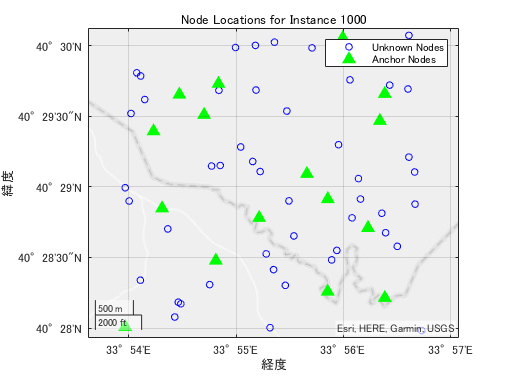


% --- Final Visualization to Validate Data ---

% Load the last generated instance for visualization
lastInstanceFile = sprintf('data/64beacons_1000instances_noise/data_instance_%d.mat', numInstances);
loadedData = load(lastInstanceFile);
nodeLatitudes = loadedData.nodeLatitudes;
nodeLongitudes = loadedData.nodeLongitudes;
signal_strength_matrix = loadedData.signal_strength_matrix;

% Plot the locations of nodes for the last instance generated
figure;
geoplot(nodeLatitudes, nodeLongitudes, 'bo', 'MarkerSize', 5);
hold on;
geoplot(fixedAnchorLatitudes, fixedAnchorLongitudes, 'g^', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
title(sprintf('Node Locations for Instance %d', numInstances));
legend('Unknown Nodes', 'Anchor Nodes');
hold off;

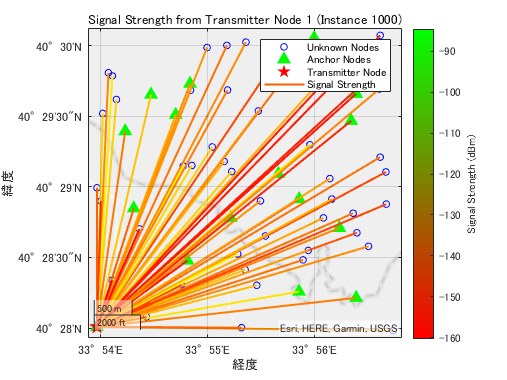


% Display an example of signal strength between the first node and others
tx_node_index = 1;
signal_strength_values = signal_strength_matrix(tx_node_index, :, 1); % Use the first simulation set for visualization

figure;
geoplot(nodeLatitudes, nodeLongitudes, 'bo', 'MarkerSize', 5);
hold on;
geoplot(fixedAnchorLatitudes, fixedAnchorLongitudes, 'g^', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
geoplot(nodeLatitudes(tx_node_index), nodeLongitudes(tx_node_index), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

for i = 1:totalNodes
    if i ~= tx_node_index && ~isnan(signal_strength_values(i))
        % Color intensity based on signal strength value (normalized for visualization)
        signal_strength = signal_strength_values(i);

        % Normalization of signal strength values to range between 0 and 1
        normalized_ss = (signal_strength - min(signal_strength_values(:))) / ...
                        (max(signal_strength_values(:)) - min(signal_strength_values(:)));

        % Interpolation between green (strong signal) and red (weak signal)
        color_intensity = [1, 1 - normalized_ss, 0];  % RGB color from green (strong) to red (weak)

        % Plot line from transmitter to receiver with appropriate color
        geoplot([nodeLatitudes(tx_node_index), nodeLatitudes(i)], ...
                [nodeLongitudes(tx_node_index), nodeLongitudes(i)], ...
                'Color', color_intensity, 'LineWidth', 1.5);
    end
end

title(sprintf('Signal Strength from Transmitter Node %d (Instance %d)', tx_node_index, numInstances));
legend('Unknown Nodes', 'Anchor Nodes', 'Transmitter Node', 'Signal Strength');
hold off;

% Add a colorbar to represent signal strength values in dBm
colormap(flipud([linspace(0, 1, 256)', linspace(1, 0, 256)', zeros(256, 1)])); % Green to Red gradient
colorbar;
caxis([min(signal_strength_values(:)), max(signal_strength_values(:))]);
ylabel(colorbar, 'Signal Strength (dBm)');


% --- Helper functions ---

% Save function for parfor compatibility

function parsave(filename, nodeLatitudes, nodeLongitudes, signal_strength_matrix)
    save(filename, 'nodeLatitudes', 'nodeLongitudes', 'signal_strength_matrix');
end

% Progress update callback using persistent counter
function updateProgress(~, totalInstances, printInterval)
    persistent count;
    if isempty(count)
        count = 0;
    end
    count = count + 1;
    if mod(count, printInterval) == 0 || count == totalInstances
        fprintf('  Completed: %d / %d (%.1f%%)\n', count, totalInstances, 100*count/totalInstances);
    end
    if count == totalInstances
        count = 0;  % Reset for next run
    end
end